clear; clc; format shortE
restoredefaultpath; 
addpath( "Temp_Profiles/" )
addpath( "Dimensionless_Numbers/")
addpath( "MATLAB2Tex/")
texFile = "tex.txt";
figFolder = "figFolder";

## Constants 

mu = 4.18e-5; % [kg / (m^2 s)]
k_fluid = 0.3218; % [W / (m K)]
rho = 0.05763; % [kg / m^3]
kc = 8.11; % [W / (m K)]
k = 17; % [W / (m K)]
Rv = 10e-3; % [m]
Q = 750e6; % [MW]
Vtot = 125; % [m^3]
Cp = 5.193e3; % [J / (kg K)]
step = 1e-5; % [m]

## Base Values 

Tinf_base = 600; % [C]
Uinf_base = 1.2089; % [m / s] 
dC_base = 5e-3; % [m]
Hg_base = 5.6e3; % [W / (m K)]
dG_base = 5e-3; % [m]
Rfoc_base = 50e-3; % [m]
R_base = Rfoc_base + dG_base + dC_base; % [m] 
n = 675000; 
q_base = Q / ( n * 4 / 3 * pi * R_base^3 ) % [W / m^3]

q_base =    1.2280e+06


tableNames = {'Fuel Melt Temperature', 'Clad Melt Temperature'};

## Base Case 

subsection( texFile, "Base Case", 'w')
[TmeltClad, TmeltFuel, totalRange, totalProfile] = getMinMelt(Uinf_base, rho, mu, Cp, k_fluid, step, Rv, Rfoc_base, dG_base, dC_base, Tinf_base, q_base, kc, k, Hg_base );
f = figure();   
    plot( totalRange, totalProfile )
    title( "Base Case Temperature Profile")
    xlabel( "Raidal Position [m]")
    ylabel( "Temperature [C]")
tempTables = array2table( [TmeltFuel, TmeltClad],  'VariableNames', tableNames)

tempTables = 1×2 table
    Fuel Melt Temperature    Clad Melt Temperature
    _____________________    _____________________

         2.1020e+03               1.0192e+03      


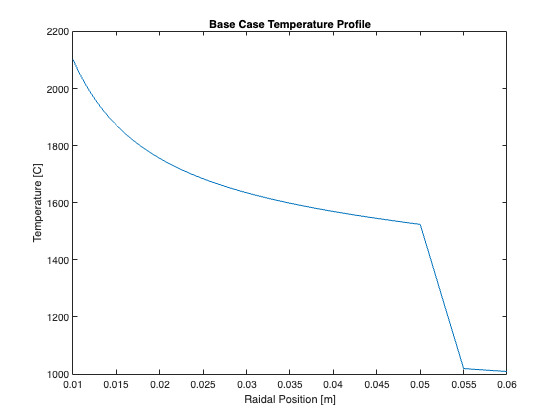

fig2Tex( f, "base", texFile, "Base Case Temperature Profile", 'a', figFolder );

table2Tex( tempTables, texFile, "Minimum Melting Temperatures for each region", 'long', 'a', 5, 0)

## Coolant Temperature Variations

subsection( texFile, "Coolant Temperature Parametric Study", 'a')
Tinf = [500; 550; 600; 650; 700]; % [C]

[TmeltClad, TmeltFuel, totalRange, totalProfile] = getMinMelt(Uinf_base, rho, mu, Cp, k_fluid, step, Rv, Rfoc_base, dG_base, dC_base, Tinf, q_base, kc, k, Hg_base );

names = cell( 1, 5 );
for i = 1:5 
    names{ i } = sprintf( "\\(T_\\infty\\) = %d C", Tinf( i ) );
end 
f = figure();
    plot( totalRange, totalProfile )   
    title( "Variable Coolant Temperature Temperature Profiles")
    xlabel( "Radial Position [m]")
    ylabel( "Temperature [C]")
    legend( names, 'Interpreter','latex', 'Location', 'best')
tempTables = array2table( [TmeltFuel, TmeltClad],  'VariableNames', tableNames)

tempTables = 5×2 table
    Fuel Melt Temperature    Clad Melt Temperature
    _____________________    _____________________

         2.0020e+03               9.1918e+02      
         2.0520e+03               9.6918e+02      
         2.1020e+03               1.0192e+03      
         2.1520e+03               1.0692e+03      
         2.2020e+03               1.1192e+03      


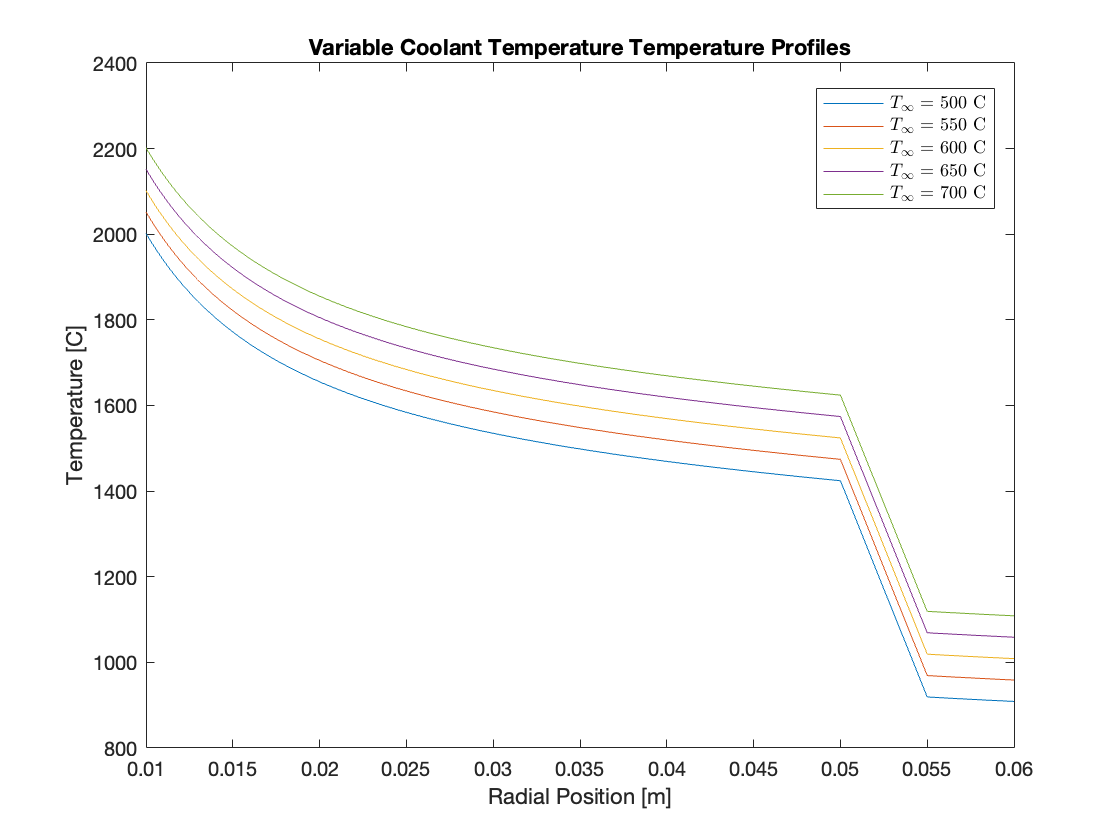

fig2Tex( f, "Tinf", texFile, "Parametric Study of Coolant Temperature", 'a', figFolder );

table2Tex( tempTables, texFile, "Minimum Melting Temperatures for each region", 'long', 'a', 5, 0)

## Coolant Velocity Variation 

subsection( texFile, "Coolant Velocity Parametric Study", 'a')
Uinf = [1.2089e-2; 1.2089e-1; 1.2089; 1.2089e2; 1.2089e3]; % [m/s]
[TmeltClad, TmeltFuel, totalRange, totalProfile] = getMinMelt(Uinf, rho, mu, Cp, k_fluid, step, Rv, Rfoc_base, dG_base, dC_base, Tinf_base, q_base, kc, k, Hg_base );
names = cell( 1, 5 );
for i = 1:5 
    names{ i } = sprintf( "\\(U_\\infty\\) = %.3e m s\\(^{-1}\\)", Uinf( i ) );
end 
f = figure();
    plot( totalRange, totalProfile )  
    title( "Variable Coolant Velocity Temperature Profiles")
    xlabel( "Radial Position [m]")
    ylabel( "Temperature [C]")
    legend( names, 'Interpreter','latex', 'Location', 'best')
tempTables = array2table( [TmeltFuel, TmeltClad],  'VariableNames', tableNames)

tempTables = 5×2 table
    Fuel Melt Temperature    Clad Melt Temperature
    _____________________    _____________________

         4.3456e+03               3.2628e+03      
         2.8355e+03               1.7526e+03      
         2.1020e+03               1.0192e+03      
         1.7308e+03               6.4798e+02      
         1.6999e+03               6.1703e+02      


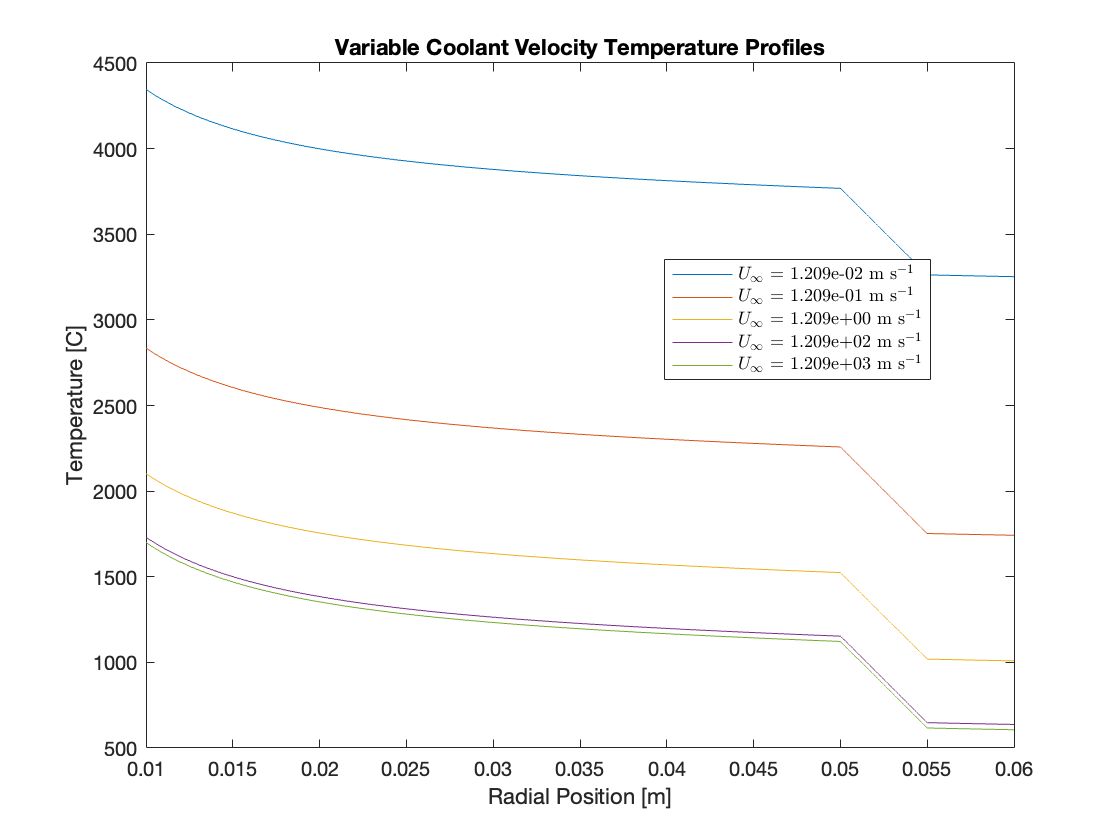

fig2Tex( f, "Uinf", texFile, "Parametric Study of Coolant Velocity", 'a', figFolder );

table2Tex( tempTables, texFile, "Minimum Melting Temperatures for each region", 'long', 'a', 5, 0)

## Cladding Thickness Variation 

subsection( texFile, "Cladding Thickness Parametric Study", 'a')
dC = [3; 4; 5; 6; 7] .* 1e-3; % [m]
f = figure();   
    
for i = 1:5
[TmeltClad( i ), TmeltFuel( i ), totalRange, totalProfile] = getMinMelt(Uinf_base, rho, mu, Cp, k_fluid, step, Rv, Rfoc_base, dG_base, dC( i ), Tinf_base, q_base, kc, k, Hg_base );
    hold on 
    plot( totalRange, totalProfile )
    hold off 
    names{ i } = sprintf( '\\(\\Delta\\)C = %1.0d m', dC( i ));
end 
    title( "Variable Cladding Thickness Temperature Profiles")
    xlabel( "Radial Position [m]")
    ylabel( "Temperature [C]")
    legend( names, 'Interpreter','latex', 'Location', 'best')
tempTables = array2table( [TmeltFuel, TmeltClad],  'VariableNames', tableNames)

tempTables = 5×2 table
    Fuel Melt Temperature    Clad Melt Temperature
    _____________________    _____________________

         2.1189e+03               1.0361e+03      
         2.1103e+03               1.0274e+03      
         2.1020e+03               1.0192e+03      
         2.0941e+03               1.0113e+03      
         2.0866e+03               1.0037e+03      


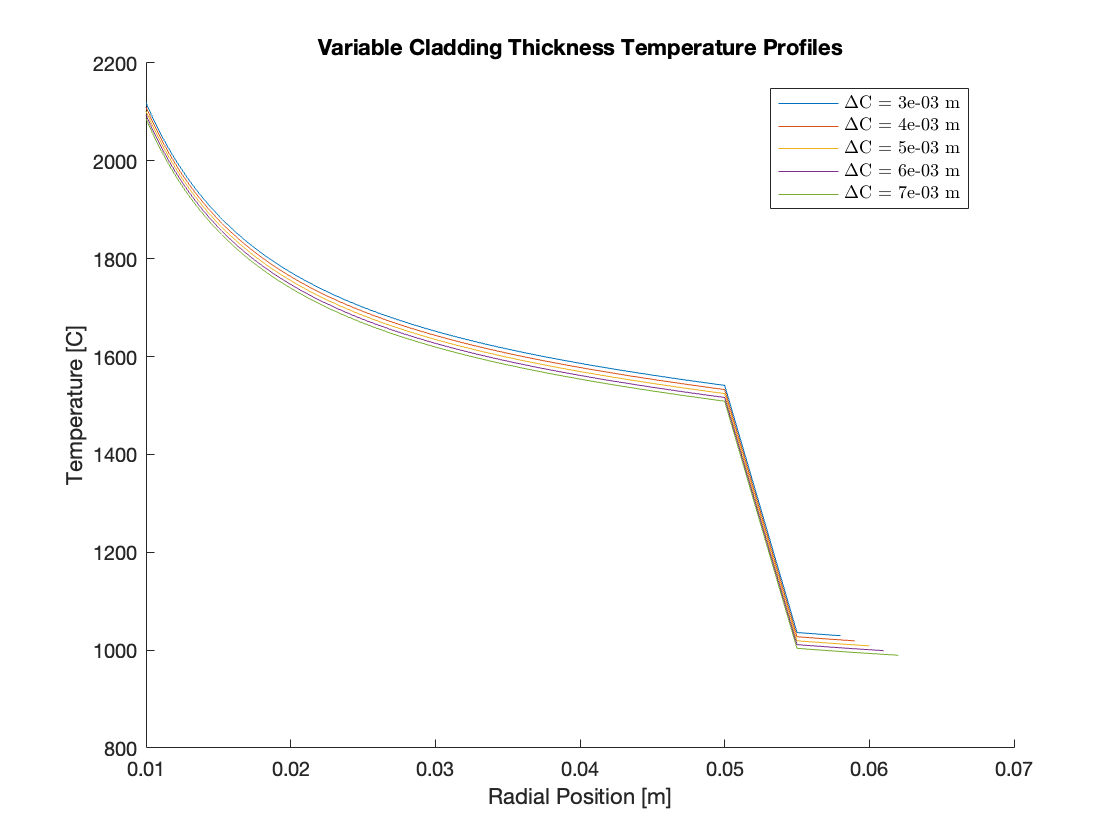

fig2Tex( f, "deltaC", texFile, "Parametric Study of Cladding Thickness", 'a', figFolder );

table2Tex( tempTables, texFile, "Minimum Melting Temperatures for each region", 'long', 'a', 5, 0)

## Gap Conductance Variation

subsection( texFile, "Gap Conductance Parametric Study", 'a')
Hg = [5.6e1; 5.6e2; 5.6e3; 5.6e4; 5.6e5]; % [W / (m K)]
f = figure();   
    
for i = 1:5
[TmeltClad( i ), TmeltFuel( i ), totalRange, totalProfile] = getMinMelt(Uinf_base, rho, mu, Cp, k_fluid, step, Rv, Rfoc_base, dG_base, dC_base, Tinf_base, q_base, kc, k, Hg( i ) );
    hold on 
    plot( totalRange, totalProfile )
    hold off 
    names{ i } = sprintf( '\\(H_g\\) = %1.1e W m\\(^{-2}\\) K\\(^{-1}\\)', Hg( i ));
end 
    title( "Variable Gap Conductance Temperature Profiles")
    xlabel( "Radial Position [m]")
    ylabel( "Temperature [C]")
    legend( names, 'Interpreter','latex', 'Location', 'best')
tempTables = array2table( [TmeltFuel, TmeltClad],  'VariableNames', tableNames)

tempTables = 5×2 table
    Fuel Melt Temperature    Clad Melt Temperature
    _____________________    _____________________

         2.4283e+03               1.0192e+03      
         2.1317e+03               1.0192e+03      
         2.1020e+03               1.0192e+03      
         2.0991e+03               1.0192e+03      
         2.0988e+03               1.0192e+03      


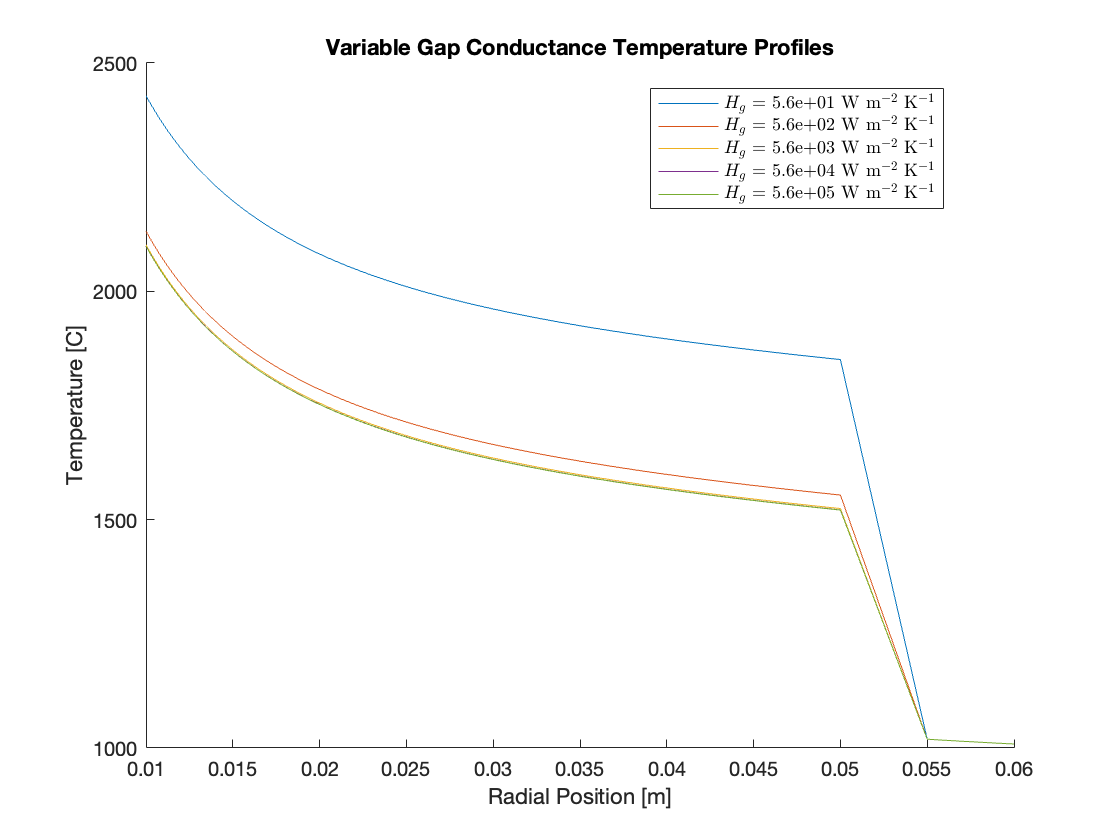

fig2Tex( f, "Hg", texFile, "Parametric Study of Gap Resistance", 'a', figFolder );

table2Tex( tempTables, texFile, "Minimum Melting Temperatures for each region", 'long', 'a', 5, 0)

## Gap Thickness Variation 

subsection( texFile, "Gap Thickness Parametric Study", 'a')
dG = [3; 4; 5; 6; 7] .* 1e-3; % [m]

f = figure();   
    
for i = 1:5
[TmeltClad( i ), TmeltFuel( i ), totalRange, totalProfile] = getMinMelt(Uinf_base, rho, mu, Cp, k_fluid, step, Rv, Rfoc_base, dG( i ), dC_base, Tinf_base, q_base, kc, k, Hg_base );

    hold on 
    plot( totalRange, totalProfile )
    hold off 
    names{ i } = sprintf( '\\(\\Delta\\)G = %1.0d m', dG( i ));
end 
    title( "Variable Gap Thickness Temperature Profiles")
    xlabel( "Radial Position [m]")
    ylabel( "Temperature [C]")
    legend( names, 'Interpreter','latex', 'Location', 'best')
    
tempTables = array2table( [TmeltFuel, TmeltClad],  'VariableNames', tableNames)

tempTables = 5×2 table
    Fuel Melt Temperature    Clad Melt Temperature
    _____________________    _____________________

         2.0827e+03               1.0248e+03      
         2.0923e+03               1.0219e+03      
         2.1020e+03               1.0192e+03      
         2.1118e+03               1.0165e+03      
         2.1216e+03               1.0138e+03      


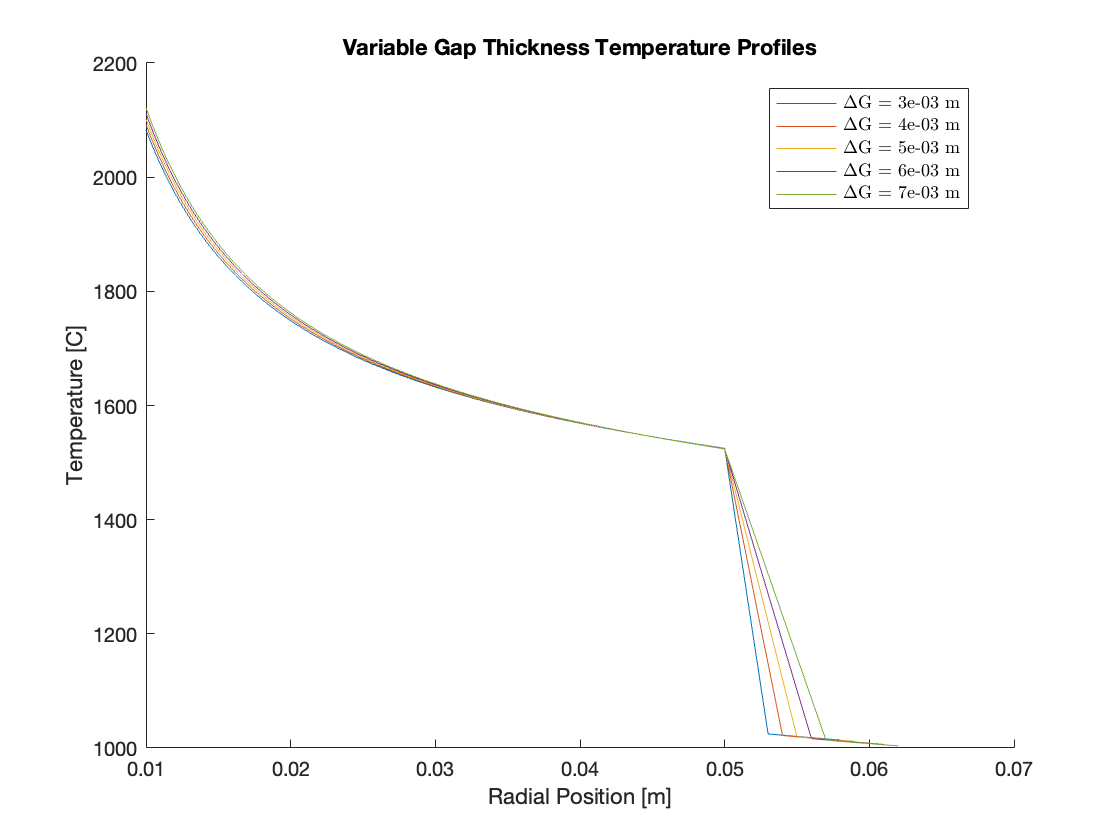

fig2Tex( f, "deltaG", texFile, "Parametric Study of Gap Thickness", 'a', figFolder );

table2Tex( tempTables, texFile, "Minimum Melting Temperatures for each region", 'long', 'a', 5, 0)

## Fuel Outer Radius Variation 

subsection( texFile, "Fuel Outer Radius Parametric Study", 'a')
Rfoc = [30; 40; 50; 60; 70] .* 1e-3; % [m]
f = figure();   
    
for i = 1:5
[TmeltClad( i ), TmeltFuel( i ), totalRange, totalProfile] = getMinMelt(Uinf_base, rho, mu, Cp, k_fluid, step, Rv, Rfoc( i ) , dG_base, dC_base, Tinf_base, q_base, kc, k, Hg_base );
    hold on 
    plot( totalRange, totalProfile )
    hold off
    names{ i } = sprintf( '\\(R_{foc}\\) = %2.0d m', Rfoc( i ));
end 
    title( "Variable Outer Fuel Radius Temperature Profiles")
    xlabel( "Radial Position [m]")
    ylabel( "Temperature [C]")  
    legend( names, 'Interpreter','latex', 'Location', 'best')
tempTables = array2table( [TmeltFuel, TmeltClad],  'VariableNames', tableNames)

tempTables = 5×2 table
    Fuel Melt Temperature    Clad Melt Temperature
    _____________________    _____________________

         1.0756e+03               7.7018e+02      
         1.5003e+03               8.8542e+02      
         2.1020e+03               1.0192e+03      
         2.9086e+03               1.1697e+03      
         3.9485e+03               1.3357e+03      


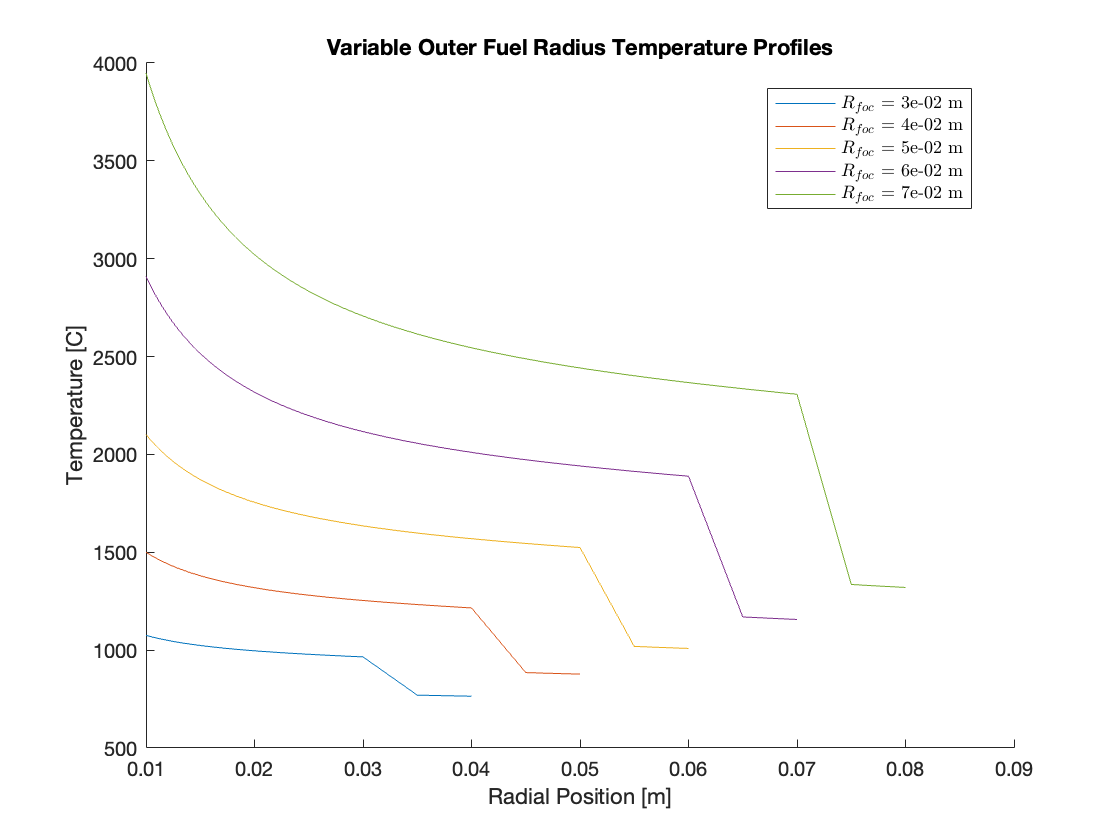

fig2Tex( f, "Rfoc", texFile, "Parametric Study of Outer Fuel Radius", 'a', figFolder );

table2Tex( tempTables, texFile, "Minimum Melting Temperatures for each region", 'long', 'a', 5, 0)

## Volumetric Heat Generatation Rate Variation 

subsection( texFile, "Volumetric Heat Generation Rate Parametric Study", 'a')
q = [1.028; 1.128; 1.228; 1.328; 1.428] * 1e6; % [W / m^3]
[TmeltClad, TmeltFuel, totalRange, totalProfile] = getMinMelt(Uinf_base, rho, mu, Cp, k_fluid, step, Rv, Rfoc_base, dG_base, dC_base, Tinf_base, q, kc, k, Hg_base );
for i = 1:5
    names{ i } = sprintf( '\\(q^{\\prime\\prime\\prime}\\) = %.3e W m\\(^{-1}\\)', q( i ));
end 
f = figure();   
    plot( totalRange, totalProfile )
    title( "Variable Volumetric Heat Generation Rate Temperature Profiles")
    xlabel( "Radial Position [m]")
    ylabel( "Temperature [C]")
    legend( names, 'Interpreter','latex', 'Location', 'best')
tempTables = array2table( [TmeltFuel, TmeltClad],  'VariableNames', tableNames)

tempTables = 5×2 table
    Fuel Melt Temperature    Clad Melt Temperature
    _____________________    _____________________

         1.8574e+03               9.5090e+02      
         1.9797e+03               9.8503e+02      
         2.1020e+03               1.0192e+03      
         2.2243e+03               1.0533e+03      
         2.3466e+03               1.0874e+03      


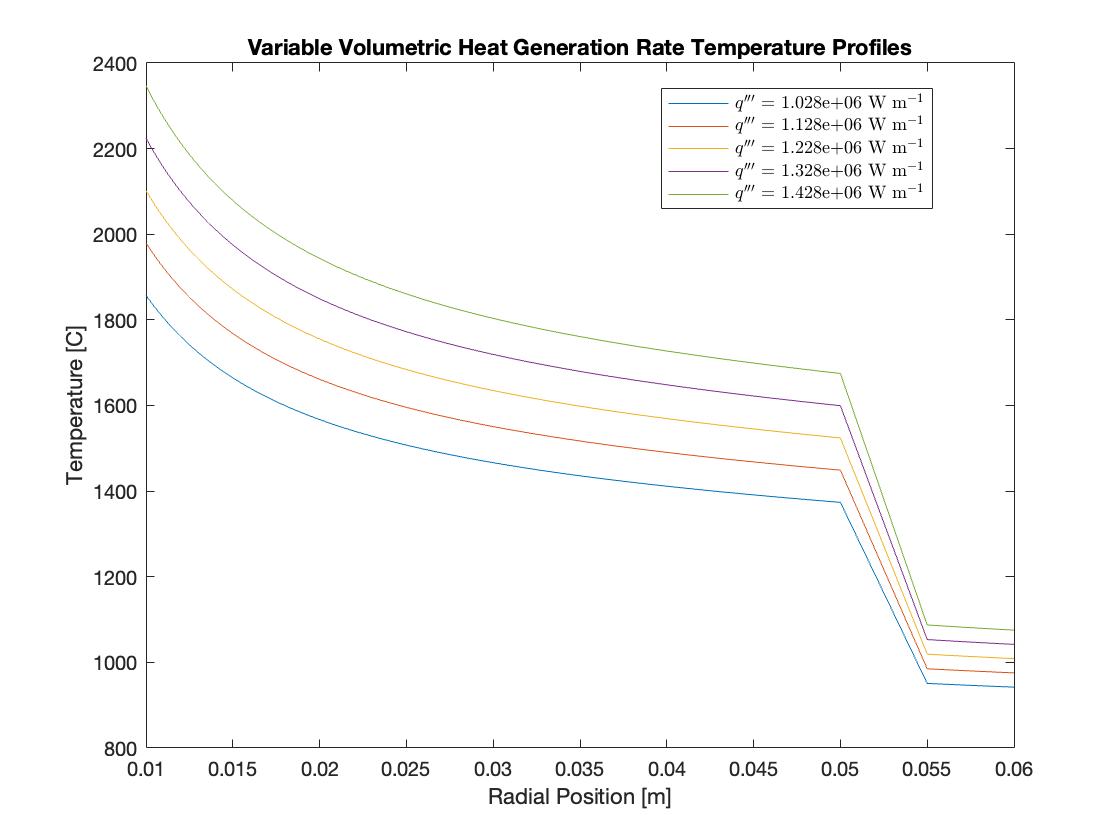

fig2Tex( f, "q", texFile, "Parametric Study of Volumetric Heat Generation Rate", 'a', figFolder );

table2Tex( tempTables, texFile, "Minimum Melting Temperatures for each region", 'long', 'a', 5, 0)
